# EXERCICIO 1

close all
clear 
clc

n=0:99

n =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


n1=0:49

n1 =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


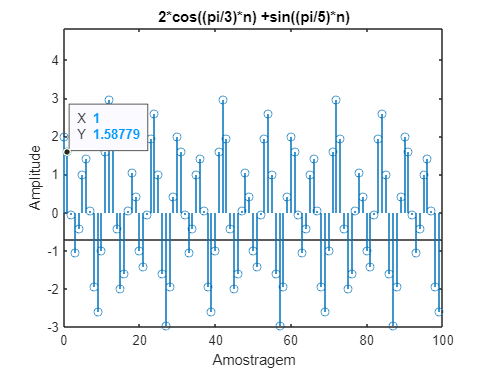


x=2*cos((pi/3)*n) +sin((pi/5)*n);

% a)
figure
stem(n,x)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*n) +sin((pi/5)*n)")


% b)

%1  
y0=indices_impares(x)

y0 =     2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511   -1.0000    2.9511   -0.4122   -1.5878    1.0489   -1.0000   -0.0489    2.5878   -1.5878   -1.9511    2.0000   -0.0489   -0.4122    1.4122   -1.9511


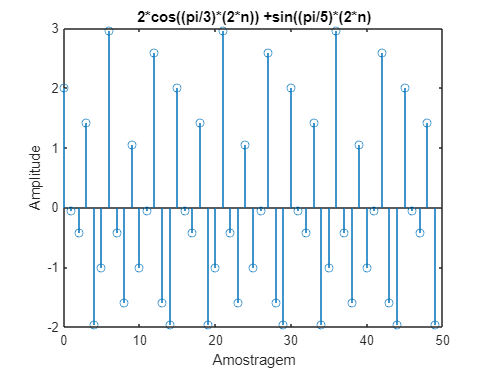

figure
stem(n1,y0)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(2*n)) +sin((pi/5)*(2*n)")


%2
%y1=2*cos((pi/3).*(-n)) +sin((pi/5).*(-n));
y1=indices_inverter(x)

y1 =    -2.5878   -1.9511    0.0489    1.4122    1.0000   -0.4122   -1.0489   -0.0489    1.5878    2.0000    0.4122   -1.9511   -2.9511   -1.5878    1.0000    2.5878    1.9511   -0.0489   -1.4122   -1.0000    0.4122    1.0489    0.0489   -1.5878   -2.0000   -0.4122    1.9511    2.9511    1.5878   -1.0000   -2.5878   -1.9511    0.0489    1.4122    1.0000   -0.4122   -1.0489   -0.0489    1.5878    2.0000    0.4122   -1.9511   -2.9511   -1.5878    1.0000    2.5878    1.9511   -0.0489   -1.4122   -1.0000


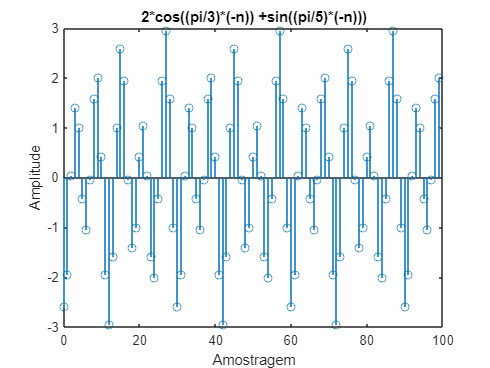

figure
stem(n,y1)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(-n)) +sin((pi/5)*(-n)))")

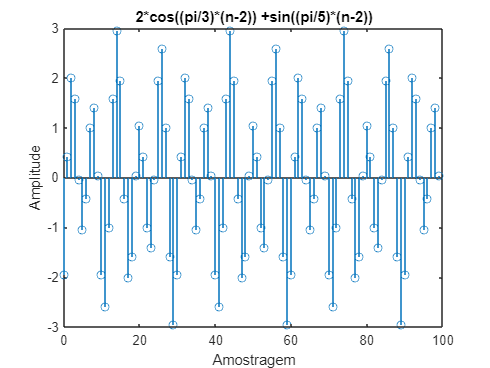


%3
y2=2*cos((pi/3)*(n-2)) +sin((pi/5)*(n-2));
figure
stem(n,y2)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(n-2)) +sin((pi/5)*(n-2))")

y20=indices_shift(x,4)

y20 =     1.5878   -0.0489   -1.0489   -0.4122    1.0000    1.4122    0.0489   -1.9511   -2.5878   -1.0000    1.5878    2.9511    1.9511   -0.4122   -2.0000   -1.5878    0.0489    1.0489    0.4122   -1.0000   -1.4122   -0.0489    1.9511    2.5878    1.0000   -1.5878   -2.9511   -1.9511    0.4122    2.0000    1.5878   -0.0489   -1.0489   -0.4122    1.0000    1.4122    0.0489   -1.9511   -2.5878   -1.0000    1.5878    2.9511    1.9511   -0.4122   -2.0000   -1.5878    0.0489    1.0489    0.4122   -1.0000


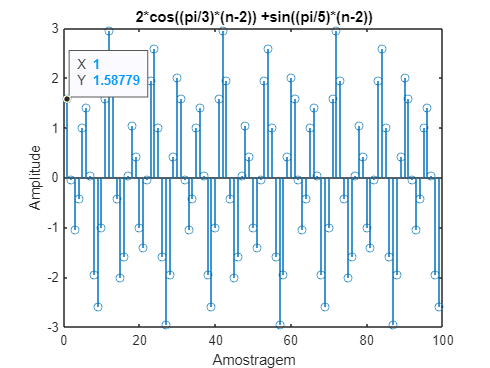


figure
stem(y20)
xlabel("Amostragem")
ylabel("Amplitude")
title("2*cos((pi/3)*(n-2)) +sin((pi/5)*(n-2))")

% %4
% y3=2*cos((pi/3)*(n*cos((pi/2)*n))) +sin((pi/5)*(n*cos((pi/2)*n)));
% figure
% stem(n,y3)
% xlabel("Amostragem")
% ylabel("Amplitude")
% title("2*cos((pi/3)*(n*cos(pi/2*n))) +sin((pi/5)*(n*cos(pi/2*n)))")

% % c)
% parteimpar = -x
% figure
% stem(n,parteimpar)
% xlabel("Amostragem")
% ylabel("Amplitude")
% title("Parte impar")
% 
% 

## EXERCICIO 2

% A= 0.5;
% B= 2;
% 
% % y=A*x + B
% 
% % a) i
% x1=ones(99);
% y1=zeros(99);
% for i=0:99
%     y1(i)=A*x1(i)+B;
% end
% figure
% plot(y1);
% 
% % a) ii
% 
% % a) iii

## Funções

function comprimido = indices_impares(vetor)
    comprimido = vetor(1:2:end);
end


function reverso = indices_inverter(x)
    
    % Determina o tamanho do sinal de entrada
    N = length(x);
    
    % Inicializa o sinal de saída
    reverso = zeros(1,N);
    
    % Calcula o sinal reverso de x
    for n = 1:N
        reverso(n) = x(N-n+1);
    end
    
end

function shift = indices_shift(x, n)
    shift = x(n-2:length(x));
end